# Ejercicio simulación 1. MK2.

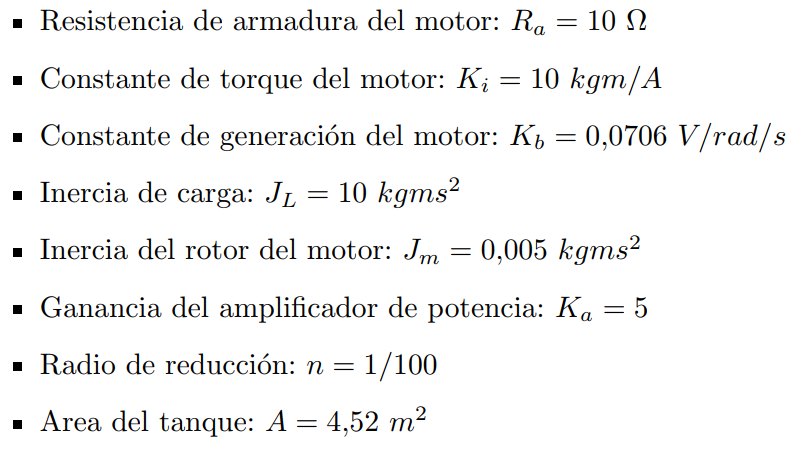

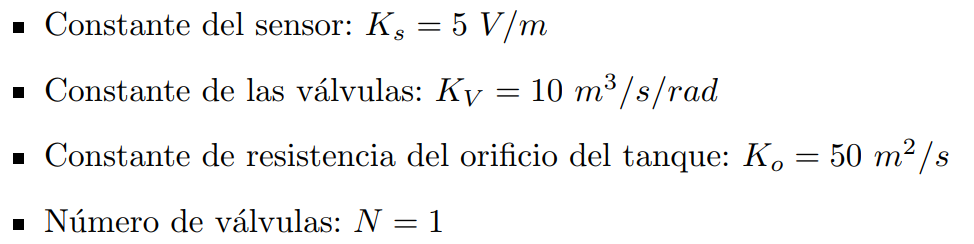

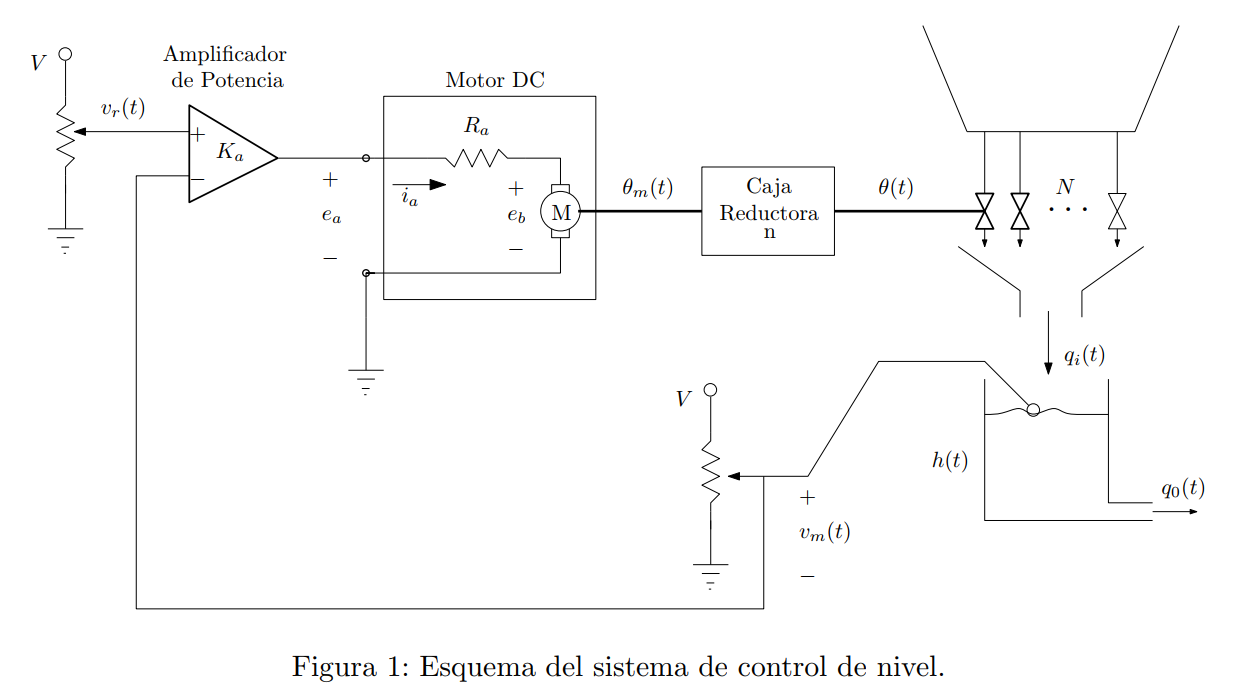

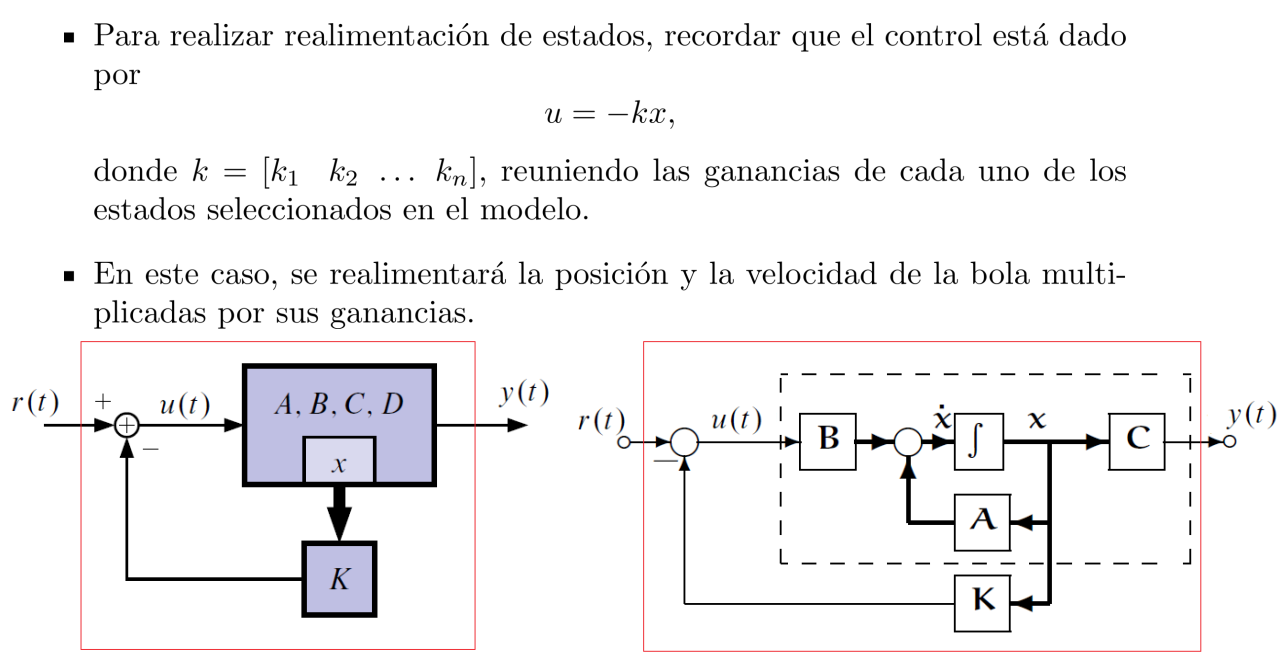

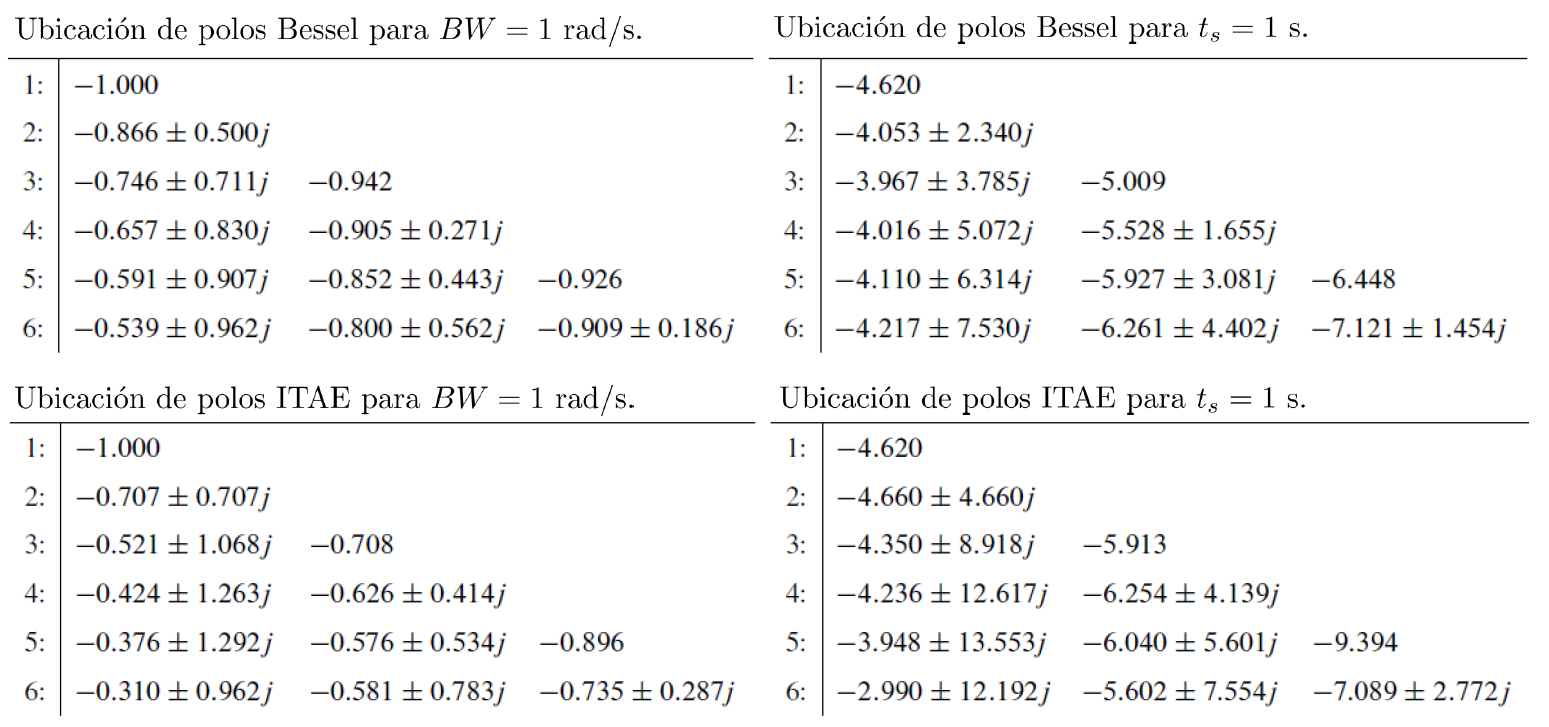

% PASO 1.
% Parámetros:
Ra=10

Ra = 10

Ki=10

Ki = 10

Kb=0.0706

Kb = 0.0706

Jl=10

Jl = 10

Jm=0.005

Jm = 0.0050

Ka=5

Ka = 5

n=1/100

n = 0.0100

a=4.52

a = 4.5200

Ks=5

Ks = 5

Kv=10

Kv = 10

Ko=50

Ko = 50

N=1

N = 1


% PASO 2.

%calculo el jacobiano del sistema en espacio de estados:
syms x [1 3]    %define x1, x2 y x3 como simbólicas
syms u

dx1=x2

$$dx1 = x_{2}$$

dx2=(Ki*(-Kb*x2+Ka*u))/(Ra*(Jm+n^2*Jl))

$$dx2 = \frac{2500\,u}{3}-\frac{353\,x_{2}}{30}$$

dx3=(N*Kv*n*x1-Ko*sqrt(x3))/a %representa la altura

$$dx3 = \frac{5\,x_{1}}{226}-\frac{1250\,\sqrt{x_{3}}}{113}$$

mat_F=[dx1;dx2;dx3]     %con parámetros numéricos

$$mat\_F = \left(\begin{array}{c} x_{2}\\ \frac{2500\,u}{3}-\frac{353\,x_{2}}{30}\\ \frac{5\,x_{1}}{226}-\frac{1250\,\sqrt{x_{3}}}{113} \end{array}\right)$$

mat_linealizada_A=jacobian(mat_F,x) %deriva respecto a x    

$$mat\_linealizada\_A = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & -\frac{353}{30} & 0\\ \frac{5}{226} & 0 & -\frac{625}{113\,\sqrt{x_{3}}} \end{array}\right)$$

mat_linealizada_B=jacobian(mat_F,u)  %deriva respecto a u

$$mat\_linealizada\_B = \left(\begin{array}{c} 0\\ \frac{2500}{3}\\ 0 \end{array}\right)$$

%Igualo a cero, h*=0, valores de estado estacionario:
x2_ss=0

x2_ss = 0

u_ss=0      %u despejado

u_ss = 0

x3_ss=1     %referencia, punto de operacion h* (1 metro por ejemplo)

x3_ss = 1

x1_ss=(Ko*sqrt(x3_ss))/(N*Kv*n)

x1_ss = 500

sustitu_mat_lin_A=double(subs(mat_linealizada_A,x3,x3_ss)) %Se sustituye x3 simbólico por valor de referencia y se convierte el tipo de variable a double

sustitu_mat_lin_A =          0    1.0000         0
         0  -11.7667         0
    0.0221         0   -5.5310


sustitu_mat_lin_B=double(subs(mat_linealizada_B,u,u_ss))   %Se sustituye u simbólico por valor

sustitu_mat_lin_B =          0
  833.3333
         0



% PASO 3
%Creo matrices de salida C y D:
C=[0 0 1]   %C debe ser estados 0 0 1

C =      0     0     1


D=0 %realimentación aunque no se "usa" en este caso se deja definida.

D = 0


% PASO 4.
[numerador,denom]=ss2tf(sustitu_mat_lin_A,sustitu_mat_lin_B,C,D)

numerador =          0         0         0   18.4366


denom =     1.0000   17.2976   65.0811         0


sisteTransferencia=tf(numerador,denom)    %tf es func transfencia.

sisteTransferencia =
 
           18.44
  ------------------------
  s^3 + 17.3 s^2 + 65.08 s
 
Continuous-time transfer function.
Model Properties


%polos=[pole(sisteTransferencia)]

% PASO 5.
tsdes=10   %10 Tiempo de asentamiento deseado 23.3 minutos aprox.

tsdes = 10

zita=1  %define si es críticamente amortiguado.

zita = 1

fna=4/(tsdes*zita) %wn=frecNaturalAmortiguada

fna = 0.4000

sistReferencia=tf([0 0 1],[1 2*zita*fna fna^2]);
polos=[pole(sistReferencia);-120] %Como la f de transfer es de grado 3, pongo el último polo negativo y relativamente grande para que no afecte a los otros dos.

polos = 1.0e+02 *

  -0.0040 + 0.0000i
  -0.0040 - 0.0000i
  -1.2000 + 0.0000i


%polos=[-3.967+3.785i -3.967-3.785i -5.009]    %Polo sacado de tabla.

mat_K=acker(sustitu_mat_lin_A,sustitu_mat_lin_B,polos)  %calcula ganancia que tiene el estado en x3 para que tienda a una referencia

mat_K =    -0.6497    0.1242  163.4584


%------------------------------INDICES DESEMPEÑO

%%% Indices de desempeño (ITAE)
tiempo_scope1 = out.ScopeData1.time;

Unable to resolve the name 'out.ScopeData1.time'.

valores_scope1 = out.ScopeData1.signals.values;

If = stepinfo(valores_scope1,tiempo_scope1);             % Tes,Ovs
% Calcular el sobrepaso
max_y = max(valores_scope1);
steady_state_value = 1;
overshoot = ((max_y - steady_state_value) / steady_state_value)*100;
fprintf('\n\n\n Indices de Desempeño \n');
fprintf(' Tiempo de Establecimiento: %f segundos \n',If.SettlingTime);
fprintf('   Sobre Paso: %f%% \n\n', overshoot);

%--------------------------------GRÁFICAS
plot(tiempo_scope1,valores_scope1,LineWidth=2);
title('Grafica 1 Nivel agua tanque');
xlabel('tiempo (s)');
ylabel('ALtura (m)');
grid on;

#### Acción integral.

%Matriz aumentada:
sustitu_mat_lin_A

sustitu_mat_lin_A =          0    1.0000         0
         0  -11.7667         0
    0.0221         0   -5.5310


sustitu_mat_lin_B

sustitu_mat_lin_B =          0
  833.3333
         0


C

C =      0     0     1


C_ampliada=[C 0]

C_ampliada =      0     0     1     0


sustitu_mat_lin_A_ampliada = [sustitu_mat_lin_A, zeros(3,1); -C 0]

sustitu_mat_lin_A_ampliada =          0    1.0000         0         0
         0  -11.7667         0         0
    0.0221         0   -5.5310         0
         0         0   -1.0000         0


sustitu_mat_lin_B_ampliada = [sustitu_mat_lin_B; 0]

sustitu_mat_lin_B_ampliada =          0
  833.3333
         0
         0



%---------------
% PASO 4.
[numerador2,denom2]=ss2tf(sustitu_mat_lin_A_ampliada,sustitu_mat_lin_B_ampliada,C_ampliada,D)

numerador2 =          0         0         0   18.4366         0


denom2 =     1.0000   17.2976   65.0811         0         0


sisteTransferencia2=tf(numerador2,denom2)    %tf es func transfencia.

sisteTransferencia2 =
 
           18.44 s
  --------------------------
  s^4 + 17.3 s^3 + 65.08 s^2
 
Continuous-time transfer function.
Model Properties


%polos_ampliados=[pole(sisteTransferencia2)]

% PASO 5.
tsdes2=10   %10 Tiempo de asentamiento deseado 23.3 minutos aprox.

tsdes2 = 10

zita2=1  %define si es críticamente amortiguado.

zita2 = 1

fna2=4/(tsdes2*zita2) %wn=frecNaturalAmortiguada

fna2 = 0.4000

sistReferencia2=tf([0 0 1],[1 2*zita2*fna2 fna2^2]);
%polos_ampliados=[pole(sistReferencia2);-120;-100] %Como la f de transfer es de grado 3, pongo el último polo negativo y relativamente grande para que no afecte a los otros dos.
polos_ampliados=[-4.016+5.072i -5.528+1.655i -4.016-5.072i -5.528-1.655i]    %Polo sacado de tabla.

polos_ampliados =   -4.0160 + 5.0720i  -5.5280 + 1.6550i  -4.0160 - 5.0720i  -5.5280 - 1.6550i



mat_K_ampliada_integral=acker(sustitu_mat_lin_A_ampliada,sustitu_mat_lin_B_ampliada,polos_ampliados) 

mat_K_ampliada_integral =     0.1068    0.0021   12.9141  -75.5904


mat_K_ampliada=mat_K_ampliada_integral(1:3)

mat_K_ampliada =     0.1068    0.0021   12.9141


mat_Ki=mat_K_ampliada_integral(4)

mat_Ki = -75.5904

%------------------------------INDICES DESEMPEÑO

%%% Indices de desempeño (ITAE)
tiempo_scope2 = out.ScopeData2.time;
valores_scope2 = out.ScopeData2.signals.values;

If = stepinfo(valores_scope2,tiempo_scope2);             % Tes,Ovs
% Calcular el sobrepaso
max_y = max(valores_scope2);
steady_state_value = 1;
overshoot = ((max_y - steady_state_value) / steady_state_value)*100;
fprintf('\n\n\n Indices de Desempeño \n');
fprintf(' Tiempo de Establecimiento: %f segundos \n',If.SettlingTime);
fprintf('   Sobre Paso: %f%% \n\n', overshoot);


%-------------------------------GRÁFICAS
plot(tiempo_scope2,valores_scope2,LineWidth=2);
title('Grafica 2 Nivel agua tanque');
xlabel('tiempo (s)');
ylabel('ALtura (m)');
grid on;